% load neural data
m1_neural = XZ98.MS{2}.FiltTraces(1801:end,XZ98.MS{2}.goodCellVec); % remove first 2 min
m2_neural = XZ91.MS{2}.FiltTraces(1801:end,XZ91.MS{1}.goodCellVec);
m1_tstamp = XZ98.TimeStamp.Ts{2}.Ms(1801:end);
m2_tstamp = XZ91.TimeStamp.Ts{2}.Ms(1801:end);
m1_neural_bined = BinData(m1_neural, 5, 'mean'); % bin to 1/3 s
m2_neural_bined = BinData(m2_neural, 5, 'mean');
m1_tstamp_bined = BinData(m1_tstamp, 5, 'mean');
m2_tstamp_bined = BinData(m2_tstamp, 5, 'mean');

tracks_matrix = h5read('Quadrant.analysis.h5','/tracks');
disp(size(tracks_matrix))

       38757           5           2           2



% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix = fillmissing(tracks_matrix, 'movmean', 7);
% read timestamp
tstamp = csvread('timeStamps.csv', 1);
tstamp = tstamp(251:end,2); % match video
% match neural data (remove first x minutes)
tracks_matrix = tracks_matrix(find(tstamp>=m1_tstamp(1),1):end,:,:,:);
tstamp = tstamp(find(tstamp>=m1_tstamp(1),1):end);

% bin Data
tracks_bined = BinData(tracks_matrix, 10, 'mean');
time_bined = BinData(tstamp, 10, 'mean');
% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));

% quadrant center
qcenter = [249,295]; %[xcenter, ycenter]
qcode = [head_coord(:,:,1,1)<=qcenter(1), head_coord(:,:,2,1) > qcenter(2), head_coord(:,:,1,2)<=qcenter(1),...
    head_coord(:,:,2,2)>qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2,qcode(:,3)+qcode(:,4)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;


q_diff = diff(qseries,[],2);
p_time_spent_together = sum(q_diff == 0)/length(q_diff)

p_time_spent_together = 0.1800

p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff)

p_time_spent_neighbor = 0.5308

p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff)

p_time_spent_diag = 0.2892

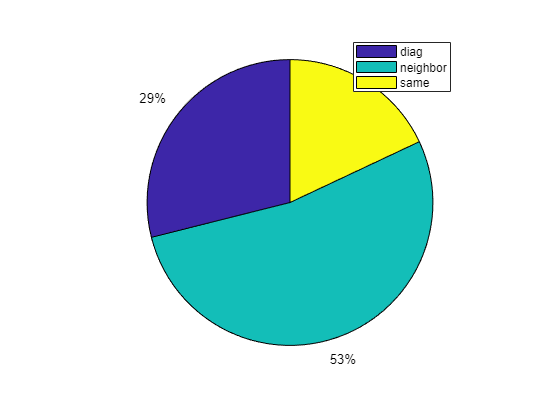

figure, pie([p_time_spent_diag,p_time_spent_neighbor,p_time_spent_together]);legend({'diag','neighbor','same'})

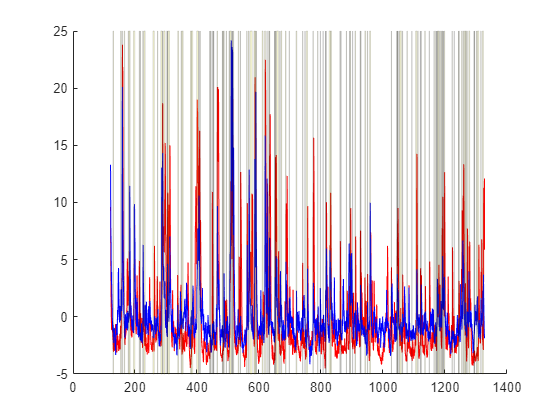

% get PLS
[PLS1, PLS2, USV] = GetPLSC(m1_neural, m2_neural);
figure, ax = axes('NextPlot','add'); plot(ax,m1_tstamp/1000,-PLS1(:,1),'r'); plot(ax,m2_tstamp/1000,-PLS2(:,1),'b')
% find same quadrant time point
same_q_t = find(qseries(:,1) == qseries(:,2));
% find consecutive bouts (apply threshold > )
onset_t = cat(1,1,find(diff(same_q_t)>2)+1);
offset_t = same_q_t([onset_t(2:end)-1;length(same_q_t)]);
onset_t = time_bined(same_q_t(onset_t))/1000;
offset_t = time_bined(offset_t)/1000;
% patch same quadrant period
for i = 1:length(onset_t)
    patch(ax,[onset_t(i),offset_t(i),offset_t(i),onset_t(i)],[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],'y','FaceAlpha',0.15, 'EdgeAlpha',0.14);
end

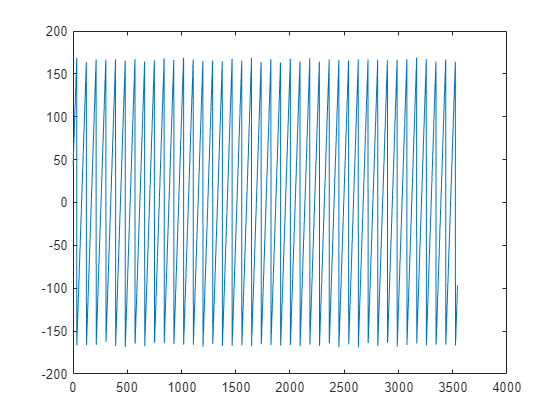

% timestamp map
[idx1,idx2,tdifference] = TStampAlign(time_bined,m1_tstamp_bined);
figure, plot(tdifference);

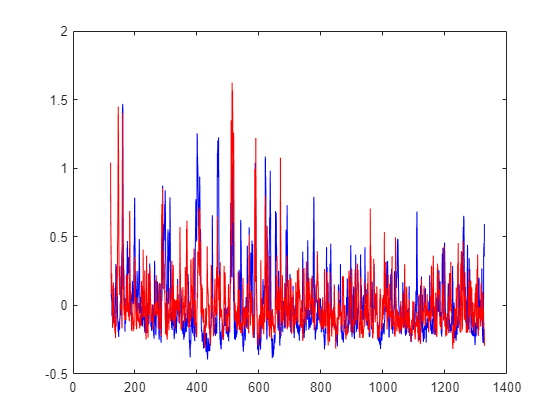

m1_tstamp_bined = m1_tstamp_bined(idx2,:);
m2_tstamp_bined = m2_tstamp_bined(idx2,:);
m1_neural_bined = m1_neural_bined(idx2,:);
m2_neural_bined = m2_neural_bined(idx2,:);
S_idx = find(qseries(:,1) == qseries(:,2)); % same index
N_idx = find(or(abs(qseries(:,1)-qseries(:,2)) == 1, abs(qseries(:,1)-qseries(:,2)) == 3)); % neighbor index
D_idx = find(abs(qseries(:,1)-qseries(:,2)) == 2); % diagonal index
Y = zeros(length(idx2),1); Y(S_idx) = 1; Y(N_idx) = 2; Y(D_idx) = 3;
% prepare training/test set
m1_neural_bined = zscore(m1_neural_bined);
m2_neural_bined = zscore(m2_neural_bined);
% plot average plot
figure, plot(m1_tstamp_bined/1000, mean(m1_neural_bined,2),'b-'), hold on, plot(m2_tstamp_bined/1000, mean(m2_neural_bined,2),'r-')

% neighbor vs diag
fold = 10;
Y_temp = Y; Y_temp([S_idx;N_idx]) = 0; Y_temp(D_idx) = 1;
part_temp = cvpartition(Y_temp, 'KFold', fold);
perform = [];
perform_shifted = [];
for k = 1:fold*10
    foldN = mod(k, fold); if foldN == 0 foldN = fold; end
    training_idx = training(part_temp, foldN);
    Y_temp_training = Y_temp(training_idx);
    X1_train = m1_neural_bined(training_idx,:);
    X2_train = m2_neural_bined(training_idx,:);
    Mdl1 = fitcdiscr(X1_train,Y_temp_training);
    Mdl2 = fitcdiscr(X2_train,Y_temp_training);
    Mdl3 = fitcdiscr(cat(2,X1_train,X2_train), Y_temp_training);
    % test
    val_idx = test(part_temp, foldN);
    Y_temp_val = Y_temp(val_idx);
    X1_val = m1_neural_bined(val_idx,:);
    X2_val = m2_neural_bined(val_idx,:);
    Y1_pred = predict(Mdl1, X1_val);
    Y2_pred = predict(Mdl2, X2_val);
    Y3_pred = predict(Mdl3, cat(2, X1_val, X2_val));
    perform = [perform; sum(Y_temp_val == [Y1_pred, Y2_pred, Y3_pred],1)/length(Y_temp_val)];
    if mod(k,fold) == 0
        part_temp = repartition(part_temp);
    end
    for cs = 1:10
        X1_train_shifted = circshift(X1_train, randi(size(X1_train,1)),1);
        X2_train_shifted = circshift(X2_train, randi(size(X2_train,1)),1);
        Mdl1_shifted = fitcdiscr(X1_train_shifted,Y_temp_training);
        Mdl2_shifted = fitcdiscr(X2_train_shifted,Y_temp_training);
        Mdl3_shifted = fitcdiscr(cat(2,X1_train_shifted,X2_train_shifted), Y_temp_training);
        % evaluate performance
        Y1_pred_s = predict(Mdl1_shifted, X1_val);
        Y2_pred_s = predict(Mdl2_shifted, X2_val);
        Y3_pred_s = predict(Mdl3_shifted, cat(2, X1_val, X2_val));
        perform_shifted = [perform_shifted; sum(Y_temp_val == [Y1_pred_s, Y2_pred_s, Y3_pred_s],1)/length(Y_temp_val)];
    end
end

% prepare training/test set
m1_neural_bined_dvn = m1_neural_bined;
m2_neural_bined_dvn = m2_neural_bined;
m1_neural_bined_dvn(S_idx,:) = [];
m2_neural_bined_dvn(S_idx,:) = [];
% same vs neighbor
fold = 10;
Y_temp = Y;Y_temp([N_idx]) = 1; Y_temp(D_idx) = 0; Y_temp(S_idx) = [];
part_temp = cvpartition(Y_temp, 'KFold', fold);
perform = [];
perform_shifted = [];
for k = 1:fold*10
    foldN = mod(k, fold); if foldN == 0 foldN = fold; end
    training_idx = training(part_temp, foldN);
    Y_temp_training = Y_temp(training_idx);
    X1_train = m1_neural_bined_dvn(training_idx,:);
    X2_train = m2_neural_bined_dvn(training_idx,:);
    Mdl1 = fitcdiscr(X1_train,Y_temp_training);
    Mdl2 = fitcdiscr(X2_train,Y_temp_training);
    Mdl3 = fitcdiscr(cat(2,X1_train,X2_train), Y_temp_training);
    % test
    val_idx = test(part_temp, foldN);
    Y_temp_val = Y_temp(val_idx);
    X1_val = m1_neural_bined_dvn(val_idx,:);
    X2_val = m2_neural_bined_dvn(val_idx,:);
    Y1_pred = predict(Mdl1, X1_val);
    Y2_pred = predict(Mdl2, X2_val);
    Y3_pred = predict(Mdl3, cat(2, X1_val, X2_val));
    [~,~,~,F1] = EvalPrediction(Y_temp_val, [Y1_pred, Y2_pred, Y3_pred]);
    perform = [perform; F1];
    if mod(k,fold) == 0
        part_temp = repartition(part_temp);
    end
    for cs = 1:10
        X1_train_shifted = circshift(X1_train, randi(size(X1_train,1)),1);
        X2_train_shifted = circshift(X2_train, randi(size(X2_train,1)),1);
        Mdl1_shifted = fitcdiscr(X1_train_shifted,Y_temp_training);
        Mdl2_shifted = fitcdiscr(X2_train_shifted,Y_temp_training);
        Mdl3_shifted = fitcdiscr(cat(2,X1_train_shifted,X2_train_shifted), Y_temp_training);
        % evaluate performance
        Y1_pred_s = predict(Mdl1_shifted, X1_val);
        Y2_pred_s = predict(Mdl2_shifted, X2_val);
        Y3_pred_s = predict(Mdl3_shifted, cat(2, X1_val, X2_val));
        [~,~,~,F1_shifted] = EvalPrediction(Y_temp_val, [Y1_pred_s, Y2_pred_s, Y3_pred_s]);
        perform_shifted = [perform_shifted; F1_shifted];
    end
end